DEN 435 - Homework 3 Solutions 

October 2021 Term (2110)

%%%%%%%%%%%%%%%%%%%%%

To Do:

8.10 - Analysis of a fractional factorial design

8.11 - Design generators, defining relation, aliases from the design, main effects estimate

8.17 - $3^3$ Full Factorial - done

%%%%%%%%%%%%%%%%%%%%%

## **Problem 8.10 - A **$2^{5-1}$ **Fractional Factorial Design**, p. 413 

Given:  The **identity element** I = ABCDE, the defining relation for the design.

Defining relation is the total collection of terms that are held constant to define the fraction in a fractional factorial design. This relation is used to calculate the alias structure that describes the confounding in fractional designs.

[https://support.minitab.com/en-us/minitab/18/help-and-how-to/modeling-statistics/doe/supporting-topics/factorial-and-screening-designs/what-is-a-defining-relation/](https://support.minitab.com/en-us/minitab/18/help-and-how-to/modeling-statistics/doe/supporting-topics/factorial-and-screening-designs/what-is-a-defining-relation/)

- Find generator

**Generator - **design generators determine how the fraction (or subset of runs) is selected from the full set of runs in a fractional factorial design. E.g., To construct a 1/2 fraction, 4 factor design a design generator D = ABC is *typically *used.

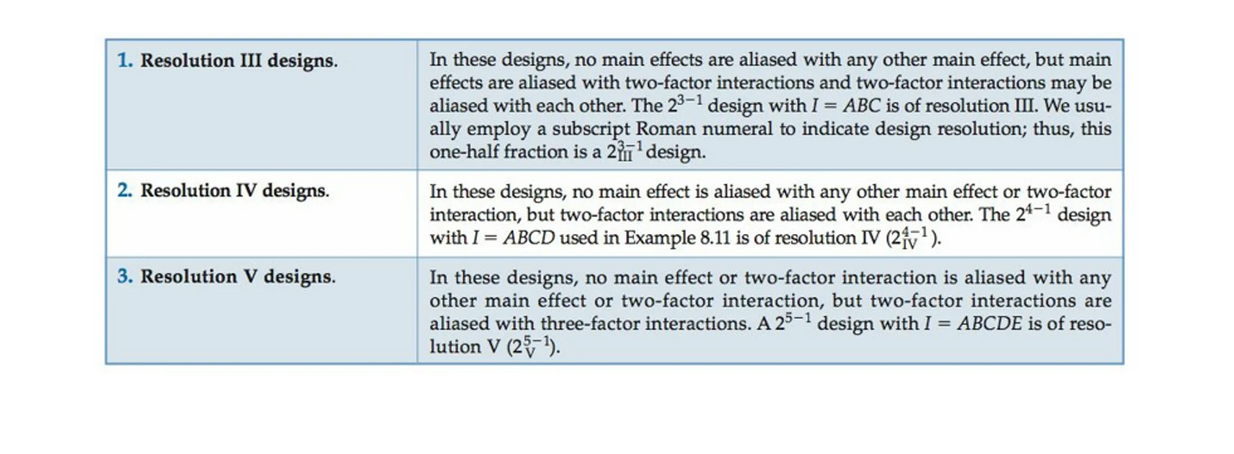

imshow('DesignResolution.png')

generators = fracfactgen('a b c d e',4,5) % A five-factor design with

generators = 5×1 cell array
    {'a'   }
    {'b'   }
    {'c'   }
    {'d'   }
    {'abcd'}


% factors a,b,c,d,e, using 2^4 = 16 runs to achieve resolution V.

The output is telling us that generator E = ABCD

2. Fractional factorial design

The design is constructed by inputting the generators (i.e. the factors) into the fractional factorial design function

[dfF,confounding] = fracfact(generators)

dfF =     -1    -1    -1    -1     1
    -1    -1    -1     1    -1
    -1    -1     1    -1    -1
    -1    -1     1     1     1
    -1     1    -1    -1    -1
    -1     1    -1     1     1
    -1     1     1    -1     1
    -1     1     1     1    -1
     1    -1    -1    -1    -1
     1    -1    -1     1     1


confounding = 16×3 cell array
    {'Term' }    {'Generator'}    {'Confounding'}
    {'X1'   }    {'a'        }    {'X1'         }
    {'X2'   }    {'b'        }    {'X2'         }
    {'X3'   }    {'c'        }    {'X3'         }
    {'X4'   }    {'d'        }    {'X4'         }
    {'X5'   }    {'abcd'     }    {'X5'         }
    {'X1*X2'}    {'ab'       }    {'X1*X2'      }
    {'X1*X3'}    {'ac'       }    {'X1*X3'      }
    {'X1*X4'}    {'ad'       }    {'X1*X4'      }
    {'X1*X5'}    {'bcd'      }    {'X1*X5'      }
    {'X2*X3'}    {'bc'       }    {'X2*X3'      }
    {'X2*X4'}    {'bd'       }    {'X2*X4'      }
    {'X2*X5'}    {'acd'      }    {'X2*X5'      }
    {'X3*X4'}    {'cd'       }    {'X3*X4'      }
    {'X3*X5'}    {'abd'      }    {'X3*X5'      }
    {'X4*X5'}    {'abc'      }    {'X4*X5'      }


Note: The design was constructed by writing down the basic design having 16 runs (a $2^4$ design in A, B, C, and D, and then setting the levels of the fifth factor E = ABCD (the generator).

An optional output from `fracfact` displays the *confounding pattern *of the design, `confounding. `Remember, anything that is confounding (or aliasing) means that a term is being masked, or is equivalent to another term in the analysis.

From the Resolution V confounding structure we see that no main effects are aliased or two-factor interactions are aliased with other main effects or two-factor interactions. From the defining relation I = ABCDE, we know that every main effect is aliased with a four-factor interaction, and **two-factor interactions are aliased with three-factor interactions** (not shown).

$[A] \rightarrow A + BCDE$ This is the 'Confounding' column, which represents the **sequence** of the fractional factorial design used to estimate the effect - i.e., the 'Term' column.


$$[AB] \rightarrow AB + CDE$$


Thus, this design should provide excellent information concerning the main effects and two-factor interactions.

3. Table to hold the DOE test matrix and the response data that corresponds to the runs in the fraction.

% Expand the DOE test matrix to include the given treatments.
% Recall that a lower-case letter in the treatment code means that that
% factor was run at a high level, i.e, 'a' means that factor A was run at a
% high level and all other factors were set at a low level.

% **** Come back to this, right now you're on a time crunch. ****
% factorCode = {'a';'b';'c';'d';'e'} % Creates a cell array
% % Create the treatment combination column
% dfFsize = size(dfF);
% treat = zeros(dfFsize(2),1) % Initialize
% for i = 1:dfFsize(1) % For every run (row), perform:
%     for k = 1:dfFsize(2) % For every factor, check its sign convention
%         if dfF(k) == 1
%             treat(i) = factorCode(k)
%         end
%     end
% end
% *********** %%%

% Create a cell array of the treatment combinations (manually)
treat = {'e';'a';'b';'abe';'c';'ace';'bce';'abc';'d';'ade';'bde';'abd';'cde';'acd';'bcd';'abcde'}

treat = 16×1 cell array
    {'e'    }
    {'a'    }
    {'b'    }
    {'abe'  }
    {'c'    }
    {'ace'  }
    {'bce'  }
    {'abc'  }
    {'d'    }
    {'ade'  }
    {'bde'  }
    {'abd'  }
    {'cde'  }
    {'acd'  }
    {'bcd'  }
    {'abcde'}


chemColor = [-.63;6.79;2.06;5.22;2.68;3.45;-2.09;4.30;2.51;6.47;1.22;4.38;1.66;5.68;1.93;4.05];

tbl = table([dfF(:,1)],[dfF(:,2)],[dfF(:,3)],[dfF(:,4)],[dfF(:,5)],[chemColor],'VariableNames',{'A','B','C','D','E','Color'})

tbl = 16×6 table
    A     B     C     D     E     Color
    __    __    __    __    __    _____

    -1    -1    -1    -1     1    -0.63
    -1    -1    -1     1    -1     6.79
    -1    -1     1    -1    -1     2.06
    -1    -1     1     1     1     5.22
    -1     1    -1    -1    -1     2.68
    -1     1    -1     1     1     3.45
    -1     1     1    -1     1    -2.09
    -1     1     1     1    -1      4.3
     1    -1    -1    -1    -1     2.51
     1    -1    -1     1     1     6.47
     1    -1     1    -1     1     1.22
     1    -1     1     1    -1     4.38
     1     1    -1    -1     1     1.66
     1     1    -1     1    -1     5.68
     1     1     1    -1    -1     1.93
     1     1     1     1     1     4.05


% see HW3_Solutions (starting at 10/11/21 17:43, 
% Fractional Replication of 8.2 - up to and including step e.) ; 
% Ex_811_FractionalFactorialDOE.mlx...]

4. Linear regression model

mdl = fitlm(tbl,'Color ~ A + B + C + D + E')

mdl = Linear regression model:
    Color ~ 1 + A + B + C + D + E

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)       3.105    0.29197     10.635    9.0172e-07
    A                0.3825    0.29197     1.3101       0.21946
    B               -0.3975    0.29197    -1.3615       0.20325
    C              -0.47125    0.29197    -1.6141       0.13759
    D                1.9375    0.29197      6.636    5.8098e-05
    E              -0.68625    0.29197    -2.3504       0.04061


Number of observations: 16, Error degrees of freedom: 10
Root Mean Squared Error: 1.17
R-squared: 0.848,  Adjusted R-Squared: 0.772
F-statistic vs. constant 

The model's adjusted R-square value is greater than 0.7, so it measures to be a good fit of the data.

5. Plot the model

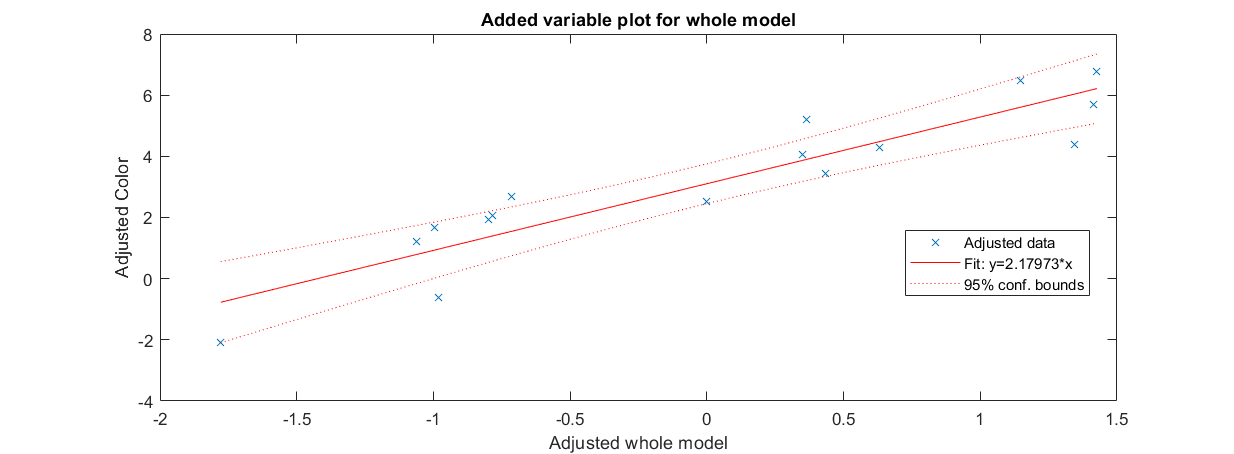

plot(mdl)

6. Plot the effects probability plot

effects = mdl.Coefficients.Estimate.*2; % Recall that the effect is equal to the regression coefficient x2
effects = effects(2:end) % Exclude the intercept value

effects =     0.7650
   -0.7950
   -0.9425
    3.8750
   -1.3725


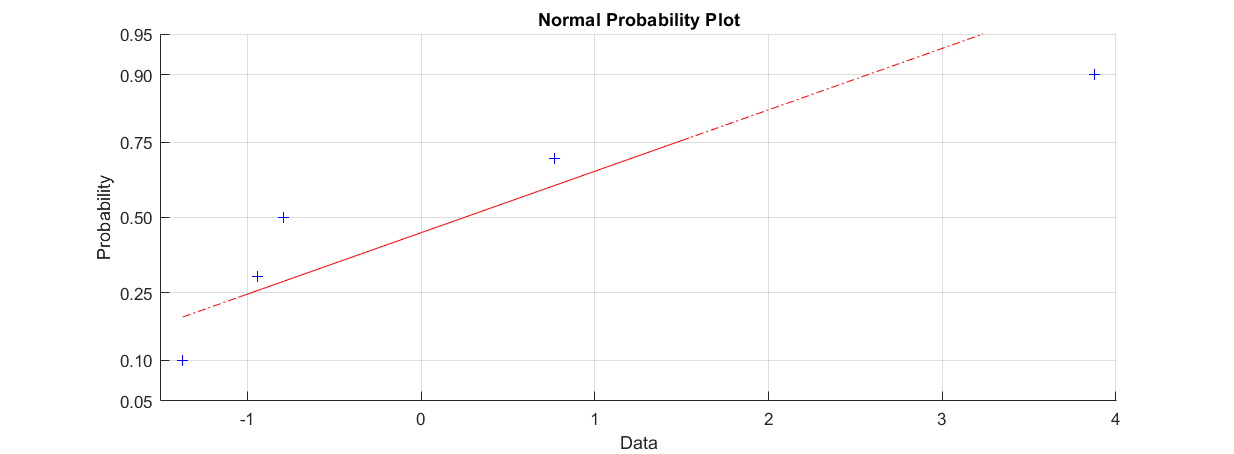

normplot(effects)

Comments: Factors E and D, and one could argue by this measure that B, are those terms that are statistically significant (have the largest effect on the response) as they lie "off" the normal probability line by the standard of the "fat pencil test."

7. Fitting a model using only the statistically significant terms:

mdl2 = fitlm(tbl,'Color ~ B + D + E')

mdl2 = Linear regression model:
    Color ~ 1 + B + D + E

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)       3.105    0.31896     9.7348    4.7846e-07
    B               -0.3975    0.31896    -1.2462       0.23646
    D                1.9375    0.31896     6.0744    5.5479e-05
    E              -0.68625    0.31896    -2.1515        0.0525


Number of observations: 16, Error degrees of freedom: 12
Root Mean Squared Error: 1.28
R-squared: 0.782,  Adjusted R-Squared: 0.728
F-statistic vs. constant model: 14.4, p-value = 0.000283

8. Residual analysis

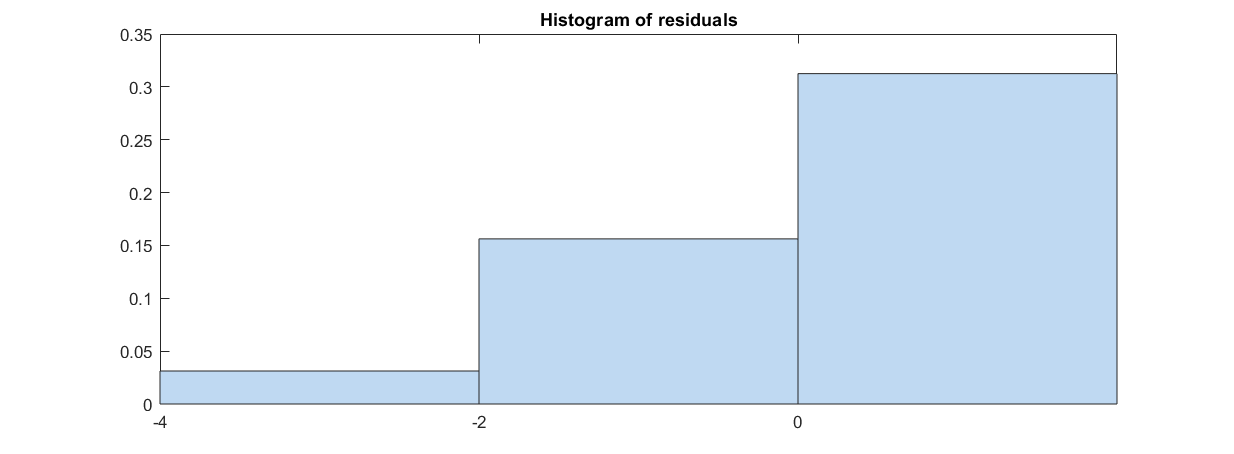

plotResiduals(mdl2)

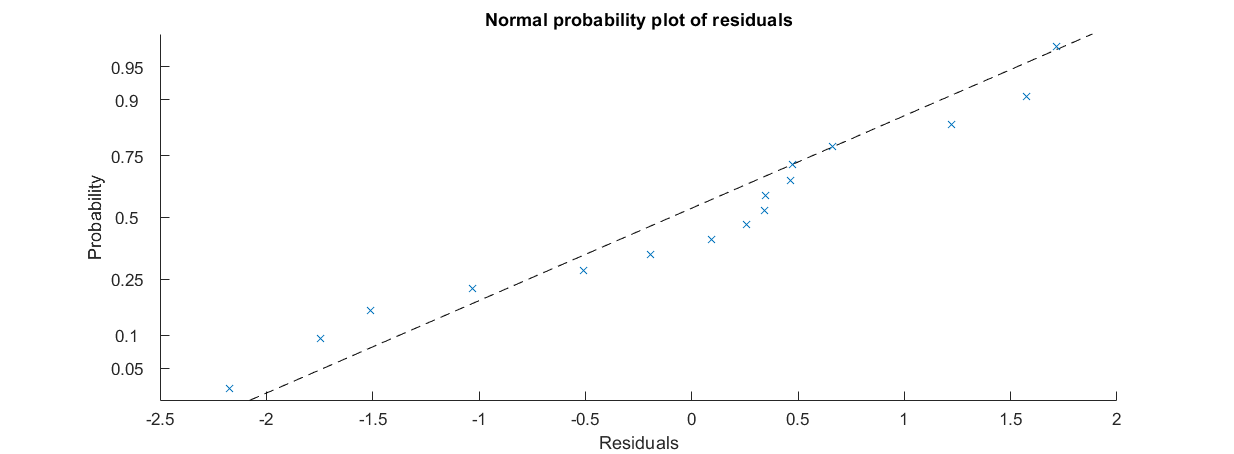

plotResiduals(mdl2,'probability')

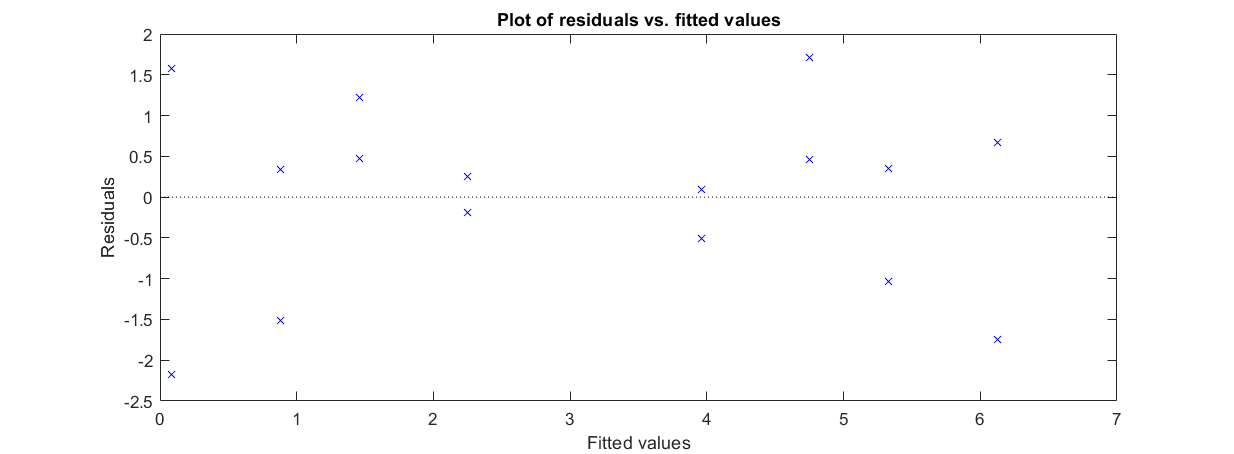

plotResiduals(mdl2,'fitted')

Fit a third model excluding factor B.

mdl3 = fitlm(tbl,'Color ~ D + E')

mdl3 = Linear regression model:
    Color ~ 1 + D + E

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)       3.105    0.32567     9.5341    3.1208e-07
    D                1.9375    0.32567     5.9492    4.8304e-05
    E              -0.68625    0.32567    -2.1072      0.055091


Number of observations: 16, Error degrees of freedom: 13
Root Mean Squared Error: 1.3
R-squared: 0.754,  Adjusted R-Squared: 0.716
F-statistic vs. constant model: 19.9, p-value = 0.00011

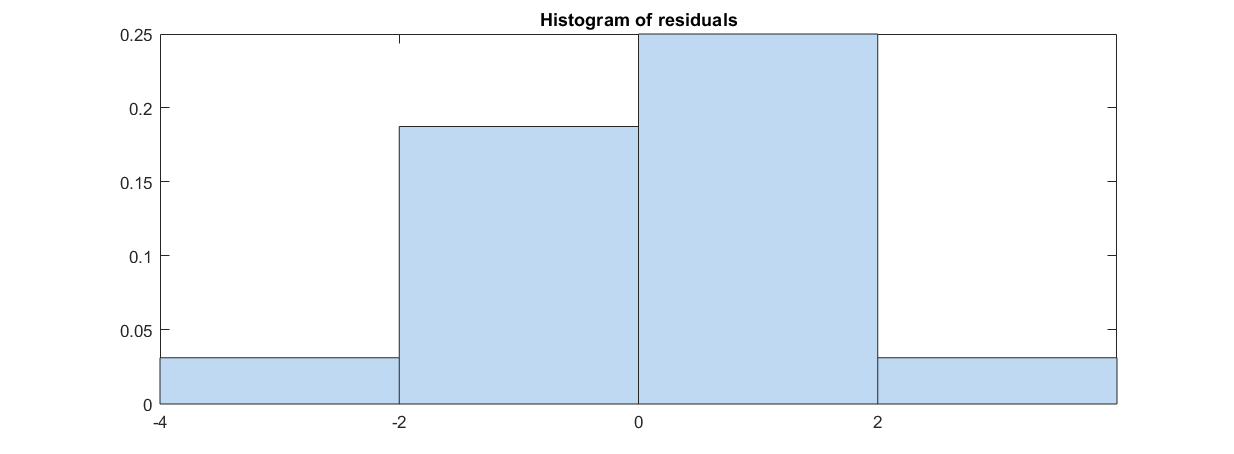

plotResiduals(mdl3)

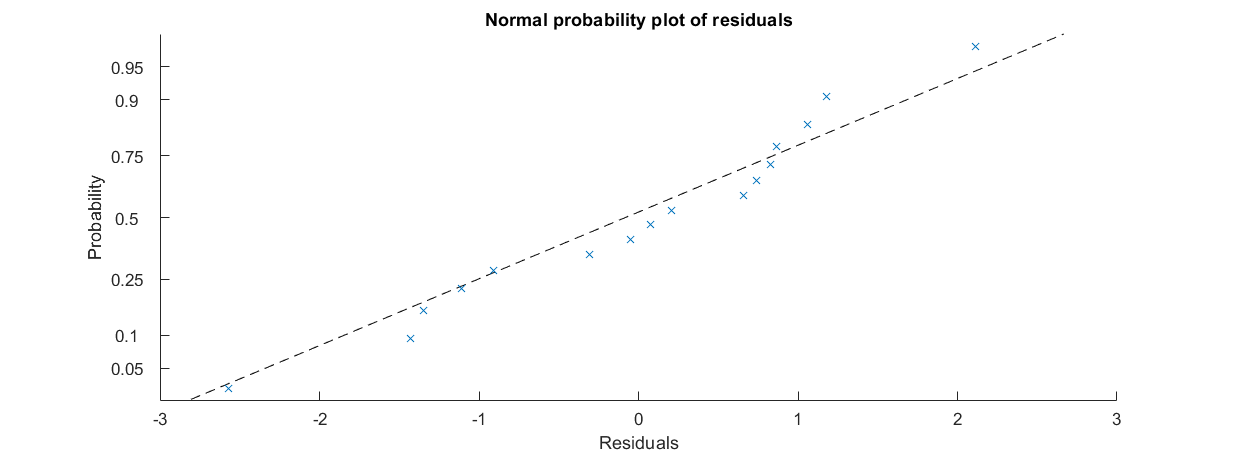

plotResiduals(mdl3,'probability')

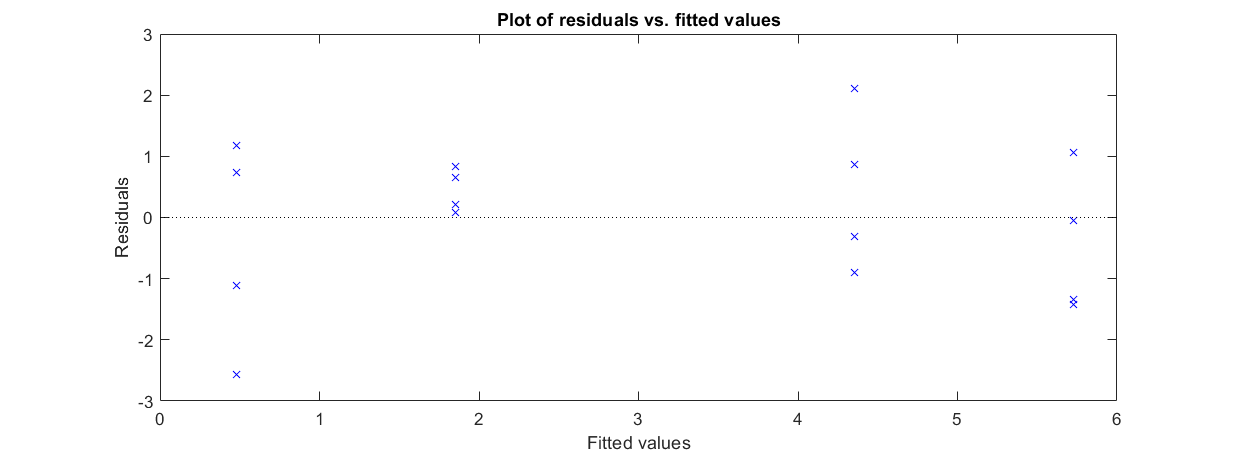

plotResiduals(mdl3,'fitted')

The histogram for `mdl3` clearly shows a more normal distribution when compared to the residuals of `mdl2, `indicating the normality assumption fits for this model.

The plot of residuals vs fitted values shows an even spread distributions throughout the domain of the surveyed design space, indicating an adequate fit of the data.

9. Collapsing the $2^{5-1}$ into a full-factorial of the significant factors

dFF = fullfact([2 2]) % Factor D is col 1, Factor E is col 2

dFF =      1     1
     2     1
     1     2
     2     2


 10/21/21.... next: insert response data to match the full factorial runs....

Response data (only that pertaining to the treatment combinations)

The experiment "cube" or design space will include only Factors D and E, with the average response superimposed on the four corners.

***The analysis is then carried out following the typical DOE procedure.***

% negative1 = [2.06;2.68;2.51;1.93]; % When both D and E are set to low values
% avgnegative1 = mean(negative1) % Average response corner
% d = [6.79;4.3;4.38;5.68]; % when D is set to high, and E is set to low
% avgd = mean(d)
% e = [-.63;-2.09;1.22;1.66]; % E is set to high, D is set to low
% avge = mean(d)
% de = [5.22;3.45;6.47;4.05]; % D and E are set to high values
% avgde = mean(de)
% combResp = [avgnegative1;avgd;avge;avgde]
% %avgCombResp = mean(combResp,2)

10. Examine data graphically

% Treatment combinations
% treat = {'(1)','d','e','de'};
% gtreat = [treat;treat;treat;treat] % Grouping variable
% boxplot(combResp,gtreat) %% Error

11. Main effects

%maineffectsplot(avgCombResp,{dFF(:,1),dFF(:,2)},'varnames',{'D','E'})

12. Create Fitted Model

%tbl = table(dFF(:,1),dFF(:,2),)

## **Problem 8.11 - A **$2^{5-2}$ **Fractional Factorial Design**, p. 413

Requirements:

a. Verify design generators used were I = ACE and I = BDE

b. Write the complete defining relation and the aliases from the design

c. Estimate the main effects

a. and b.

generators = fracfactgen('a b c d e',3,3) % Five-factor design with

generators = 5×1 cell array
    {'a'  }
    {'b'  }
    {'c'  }
    {'abc'}
    {'bc' }


% factors a, b, c, d, e using 2^3 = 8 runs to achieve resolution III.
[dfF,confounding] = fracfact(generators)

dfF =     -1    -1    -1    -1     1
    -1    -1     1     1    -1
    -1     1    -1     1    -1
    -1     1     1    -1     1
     1    -1    -1     1     1
     1    -1     1    -1    -1
     1     1    -1    -1    -1
     1     1     1     1     1


confounding = 16×3 cell array
    {'Term' }    {'Generator'}    {'Confounding'       }
    {'X1'   }    {'a'        }    {'X1 + X4*X5'        }
    {'X2'   }    {'b'        }    {'X2 + X3*X5'        }
    {'X3'   }    {'c'        }    {'X3 + X2*X5'        }
    {'X4'   }    {'abc'      }    {'X4 + X1*X5'        }
    {'X5'   }    {'bc'       }    {'X5 + X1*X4 + X2*X3'}
    {'X1*X2'}    {'ab'       }    {'X1*X2 + X3*X4'     }
    {'X1*X3'}    {'ac'       }    {'X1*X3 + X2*X4'     }
    {'X1*X4'}    {'bc'       }    {'X5 + X1*X4 + X2*X3'}
    {'X1*X5'}    {'abc'      }    {'X4 + X1*X5'        }
    {'X2*X3'}    {'bc'       }    {'X5 + X1*X4 + X2*X3'}
    {'X2*X4'}    {'ac'       }    {'X1*X3 + X2*X4'     }
    {'X2*X5'}    {'c'        }    {'X3 + X2*X5'        }
    {'X3*X4'}    {'ab'       }    {'X1*X2 + X3*X4'     }
    {'X3*X5'}    {'b'        }    {'X2 + X3*X5'        }
    {'X4*X5'}    {'a'        }    {'X1 + X4*X5'        }


10/31/21 -- **** This solution is incomplete ****

To do: a. -- Prove; b. defining relation is needed, the alias structure is shown in the 'Confounding'

column of the `confounding` variable structure, where '`X1 + X4*X5'` means that `X1` is being aliased with `X4*X5;` c. Main effects needed.

-- > See Dominik Leibel's, Oct. 2021, assignment as a possible check of the final solutions.

## **Problem 8.17 - 3^3 Full-factorial design**

- Enter Data

dFF33 = fullfact([3 3 3])

dFF33 =      1     1     1
     2     1     1
     3     1     1
     1     2     1
     2     2     1
     3     2     1
     1     3     1
     2     3     1
     3     3     1
     1     1     2



% Replace 1s and 2s with -1s and +1s, respectively, to code the design.
% Initialize array to hold coded variables
dFF33c = nan;
% Repetition structure
for i = 1:length(dFF33(:,1)) % From one to number of number of rows in column 1
    for j = 1:length(dFF33(1,:))
        if dFF33(i,j) == 1
            dFF33c(i,j) = -1;
        elseif dFF33(i,j) == 2
            dFF33c(i,j) = 0;
        elseif dFF33(i,j) == 3
            dFF33c(i,j) = 1;
        end
    end
end
dFF33c

dFF33c =     -1    -1    -1
     0    -1    -1
     1    -1    -1
    -1     0    -1
     0     0    -1
     1     0    -1
    -1     1    -1
     0     1    -1
     1     1    -1
    -1    -1     0


% Factors
fx1 = dFF33c(:,1); % Factor x1
fx2 = dFF33c(:,2); % Factor x2
fx3 = dFF33c(:,3); % Factor x3

2. Response columns

% Response vectors
avgResponse = [24;120.33;213.67;86;136.63;340.67;112.33;256.33;271.67;81;101.67;357;171.33;372;501.67;264;427;730.67;220.67;239.67;422;199;485.33;673.67;176.67;501;1010];
stdDev = [12.49;8.39;42.83;3.46;80.41;16.17;27.57;4.62;23.63;0;17.67;32.91;15.01;0;92.50;63.50;88.61;21.08;133.82;23.46;18.52;29.44;44.67;158.21;55.51;138.94;142.45];

3. Examine data graphically

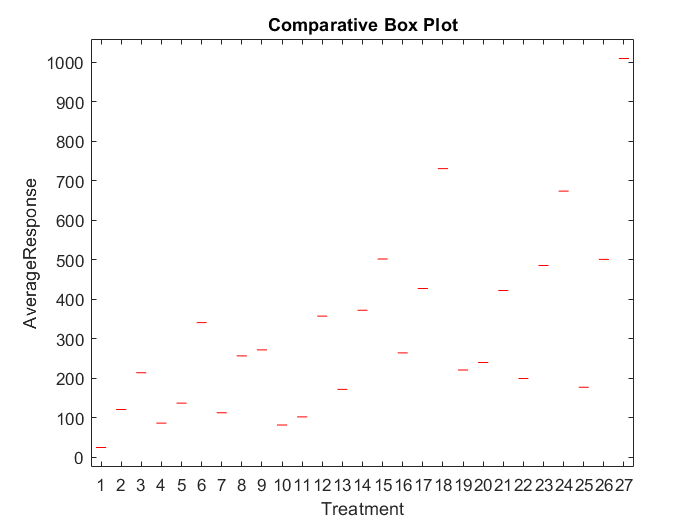

% Create a vector to hold the treatment number
% Initialize
treatment = zeros(length(dFF33c),1);
iterCount = 0;
for k = 1:length(dFF33c(:,1))
    iterCount = iterCount + 1;
    treatment(k,1) = iterCount;
end

% Box plot
boxplot(avgResponse,treatment)
ylabel('AverageResponse');
xlabel('Treatment');
title('Comparative Box Plot');


% Scatter Plots
sp1 = scatter(treatment,avgResponse)

sp1 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27]
              YData: [24 120.3300 213.6700 86 136.6300 340.6700 112.3300 256.3300 271.6700 81 101.6700 357 171.3300 372 501.6700 264 427 730.6700 220.6700 239.6700 422 199 485.3300 673.6700 176.6700 501 1010]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


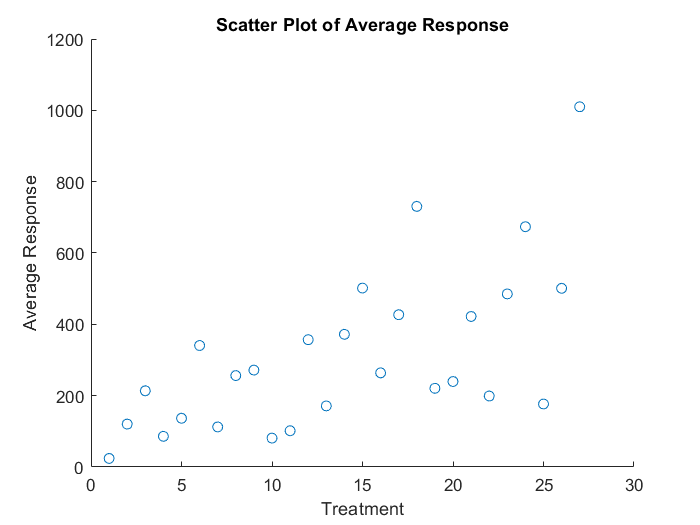

ylabel('Average Response');
xlabel('Treatment');
title('Scatter Plot of Average Response');


sp2 = scatter(treatment,stdDev)

sp2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27]
              YData: [12.4900 8.3900 42.8300 3.4600 80.4100 16.1700 27.5700 4.6200 23.6300 0 17.6700 32.9100 15.0100 0 92.5000 63.5000 88.6100 21.0800 133.8200 23.4600 18.5200 29.4400 44.6700 158.2100 55.5100 138.9400 142.4500]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


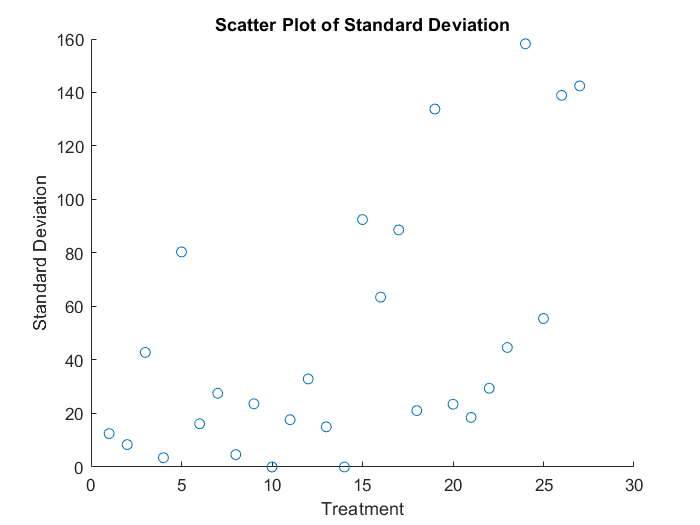

ylabel('Standard Deviation');
xlabel('Treatment');
title('Scatter Plot of Standard Deviation');

Create main effects plots for the treatment means to visualize the magnitude effect of each factor.

The main effect tells us how much the response will change per unit level change in the factor.

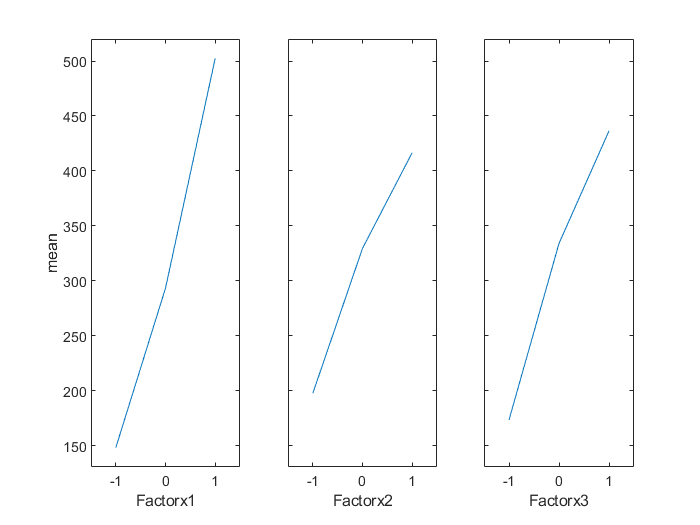

maineffectsplot(avgResponse,{fx1,fx2,fx3},'varnames',{'Factorx1','Factorx2','Factorx3'})

From visual inspection, all factors have an effect, with Factor x1 appearing to have the largest effect on the average response.

Create interaction plots to viusalize interaction effects.

An interaction occurs when the difference in response between the levels of one factor is not the same at all levels of the other factors. 

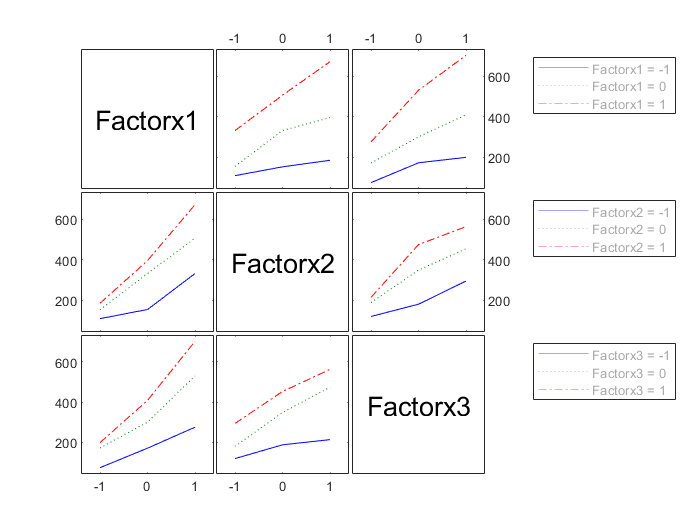

interactionplot(avgResponse,{fx1,fx2,fx3},'varnames',{'Factorx1','Factorx2','Factorx3'});

Interactions appear to minimal across all factors.

4. Create Fitted Model

The regression model

Create a table to hold the DOE test matrix and response variables.

tbl8171 = table(fx1,fx2,fx3,avgResponse,'VariableNames',{'Factorx1','Factorx2','Factorx3','AvgResponse'})

tbl8171 = 27×4 table
    Factorx1    Factorx2    Factorx3    AvgResponse
    ________    ________    ________    ___________

       -1          -1          -1             24   
        0          -1          -1         120.33   
        1          -1          -1         213.67   
       -1           0          -1             86   
        0           0          -1         136.63   
        1           0          -1         340.67   
       -1           1          -1         112.33   
        0           1          -1         256.33   
        1           1          -1         271.67   
       -1          -1           0             81   
        0          -1           0         101.67   
        1          -1           0            357   
       -1           0           0         171.33   
        0           0           0            372   
        1 

Linear regression model

Recall: Regression models describe the relationship between a response (output) variable, and one or more predictor (input variables).

Part a.

% Perform a quadratic fit to the response
 mdl8171 = fitlm(tbl8171, 'quadratic')

mdl8171 = Linear regression model:
    AvgResponse ~ 1 + Factorx1*Factorx2 + Factorx1*Factorx3 + Factorx2*Factorx3 + Factorx1^2 + Factorx2^2 + Factorx3^2

Estimated Coefficients:
                         Estimate      SE       tStat        pValue  
                         ________    ______    ________    __________

    (Intercept)           327.62     38.758      8.4532    1.7101e-07
    Factorx1                 177     17.941      9.8656    1.8872e-08
    Factorx2              109.43     17.941      6.0991    1.1803e-05
    Factorx3              131.47     17.941      7.3276    1.1808e-06
    Factorx1:Factorx2     66.028     21.973      3.0049     0.0079707
    Factorx1:Factorx3     75.471     21.973      3.4346     0.0031616
    Factorx2:F

Part b.

tbl8172 = table(fx1,fx2,fx3,stdDev,'VariableNames',{'Factorx1','Factorx2','Factorx3','StdDeviation'})

tbl8172 = 27×4 table
    Factorx1    Factorx2    Factorx3    StdDeviation
    ________    ________    ________    ____________

       -1          -1          -1          12.49    
        0          -1          -1           8.39    
        1          -1          -1          42.83    
       -1           0          -1           3.46    
        0           0          -1          80.41    
        1           0          -1          16.17    
       -1           1          -1          27.57    
        0           1          -1           4.62    
        1           1          -1          23.63    
       -1          -1           0              0    
        0          -1           0          17.67    
        1          -1           0          32.91    
       -1           0           0          15.01    
        0           0           0              

mdl8172 = fitlm(tbl8172,'linear')

mdl8172 = Linear regression model:
    StdDeviation ~ 1 + Factorx1 + Factorx2 + Factorx3

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     47.995     7.8085    6.1466    2.8587e-06
    Factorx1        11.528     9.5634    1.2054        0.2403
    Factorx2        15.323     9.5634    1.6023       0.12274
    Factorx3        29.192     9.5634    3.0524     0.0056483


Number of observations: 27, Error degrees of freedom: 23
Root Mean Squared Error: 40.6
R-squared: 0.367,  Adjusted R-Squared: 0.284
F-statistic vs. constant model: 4.45, p-value = 0.0132

Part c.

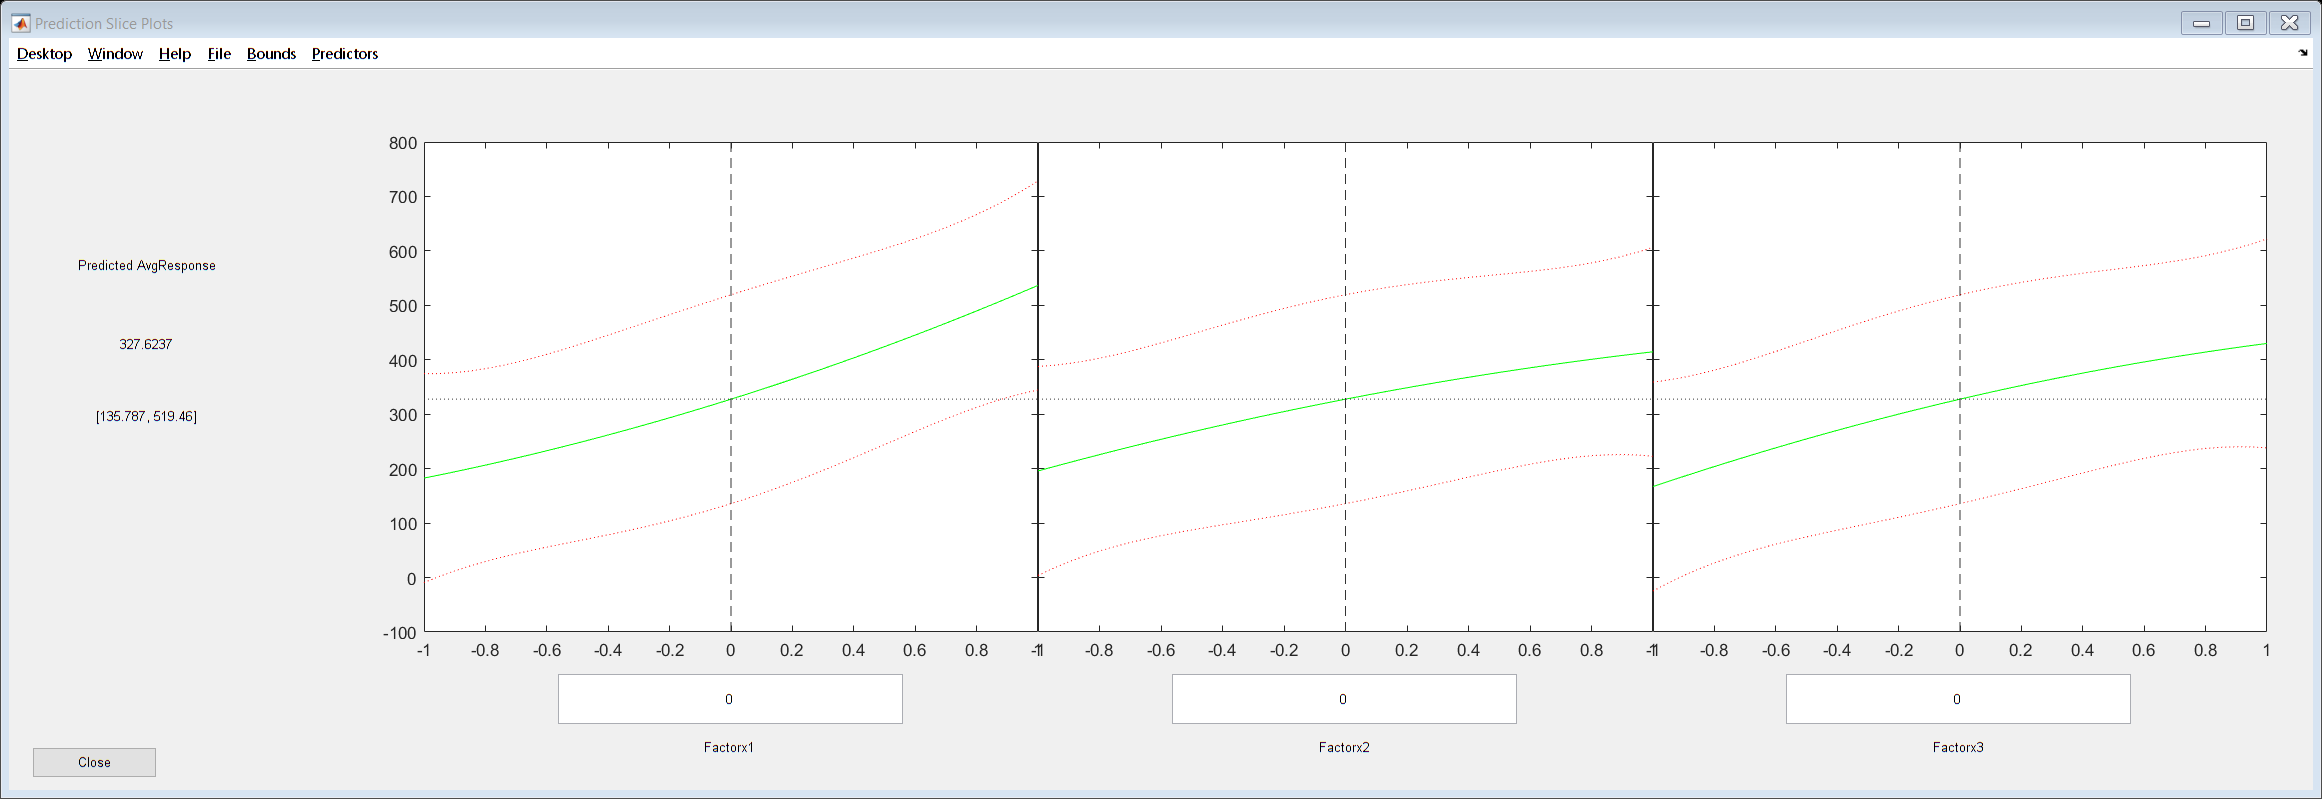

plotSlice(mdl8171)

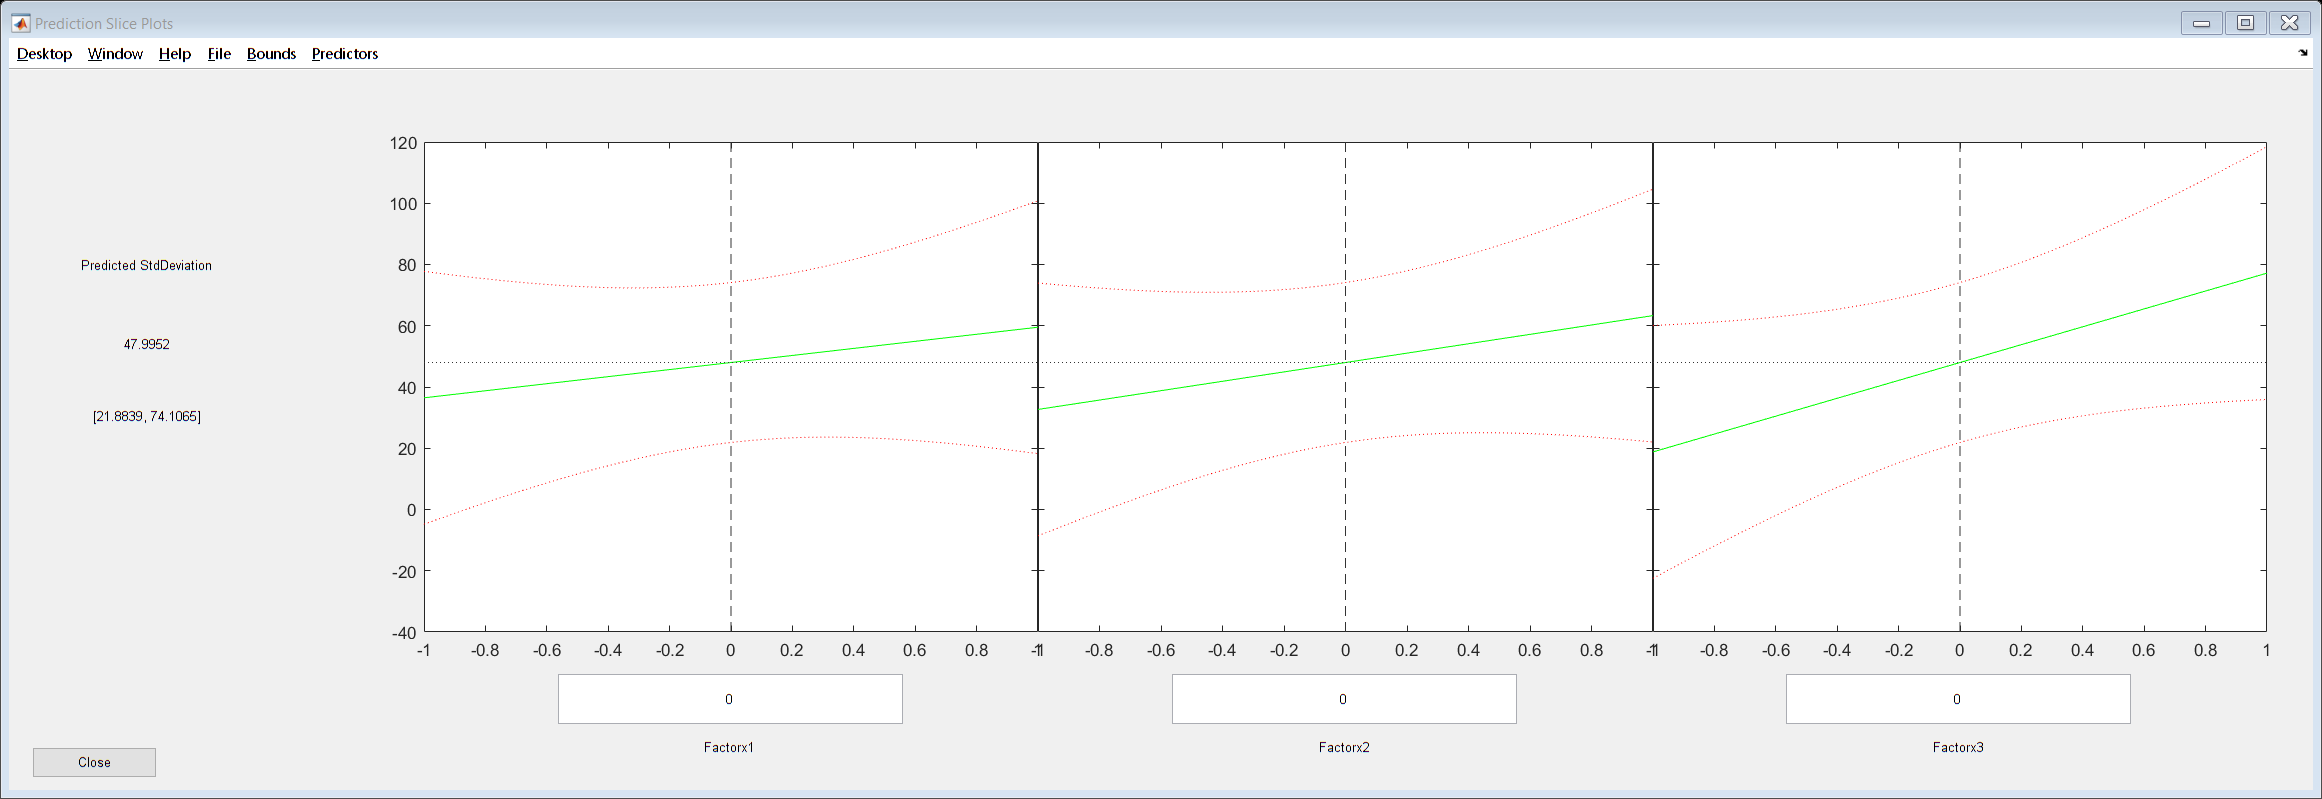

plotSlice(mdl8172)

Based on the analysis of the plot slice profiles, setting x1 = ~ 0.90, x2 = ~ 0, x3 = -0.07 will produce an avg. response equal to 500 while keeping the std. dev at a minimum.

5. Expand the problem by creating surface plots, contour plots, overlay contour plots to find the optimal region.

First, create a model of only the statistically significant terms for both the avg response model and the standard deviation model.

Consult an ANOVA table:

tbl8173 = anova(mdl8171)

tbl8173 = 10×5 table
                           SumSq       DF      MeanSq         F         pValue  
                         __________    __    __________    _______    __________

    Factorx1             5.6393e+05     1    5.6393e+05      97.33    1.8872e-08
    Factorx2             2.1553e+05     1    2.1553e+05     37.199    1.1803e-05
    Factorx3              3.111e+05     1     3.111e+05     53.693    1.1808e-06
    Factorx1:Factorx2         52317     1         52317     9.0295     0.0079707
    Factorx1:Factorx3         68350     1         68350     11.797     0.0031616
    Factorx2:Factorx3         22794     1         22794     3.9341      0.063709
    Factorx1^2               6146.1     1

From studying the ANOVA table, we see that MS (for all terms) >> MS_error, with the exception of the second-order terms. Therefore, we reject the Null Hypothesis (there are no differences in treatment means for the corresponding factor) for all terms, and therefore accept that their means differ and have an effect on the response. The exception will be the second-order terms.

#### Model for avg response with only statistically significant terms:

mdl8173 = fitlm(tbl8171,'AvgResponse ~ Factorx1 + Factorx2 + Factorx3 + Factorx1:Factorx2 + Factorx1:Factorx3 + Factorx2:Factorx3')

mdl8173 = Linear regression model:
    AvgResponse ~ 1 + Factorx1*Factorx2 + Factorx1*Factorx3 + Factorx2*Factorx3

Estimated Coefficients:
                         Estimate      SE      tStat       pValue  
                         ________    ______    ______    __________

    (Intercept)           314.67     14.448     21.78    2.1087e-15
    Factorx1                 177     17.695    10.003    3.1474e-09
    Factorx2              109.43     17.695    6.1841     4.846e-06
    Factorx3              131.47     17.695    7.4297    3.5839e-07
    Factorx1:Factorx2     66.028     21.671    3.0468     0.0063673
    Factorx1:Factorx3     75.471     21.671    3.4825     0.0023483
    Factorx2:Factorx3     43.583     21.671    2.0111      0

Note the adjusted R-Squared value for mdl8173 is slightly higher than mdl8171 (quadratic model), even though there is less terms in the model.

Model for std deviation with only statistically significant terms:

tbl8184 = anova(mdl8172)

tbl8184 = 4×5 table
                SumSq     DF    MeanSq      F        pValue  
                ______    __    ______    ______    _________

    Factorx1      2392     1      2392     1.453       0.2403
    Factorx2    4226.5     1    4226.5    2.5673      0.12274
    Factorx3     15339     1     15339    9.3174    0.0056483
    Error        37864    23    1646.2                       


Consulting the ANOVA table, we see that all factors have a larger MS than MS_error, therefore there is sufficient evidence to reject the Null Hypothesis for all terms, resulting in all terms being statistically significant.

6. Surface and contour plots

Average Response

Terms 1 and 2 only

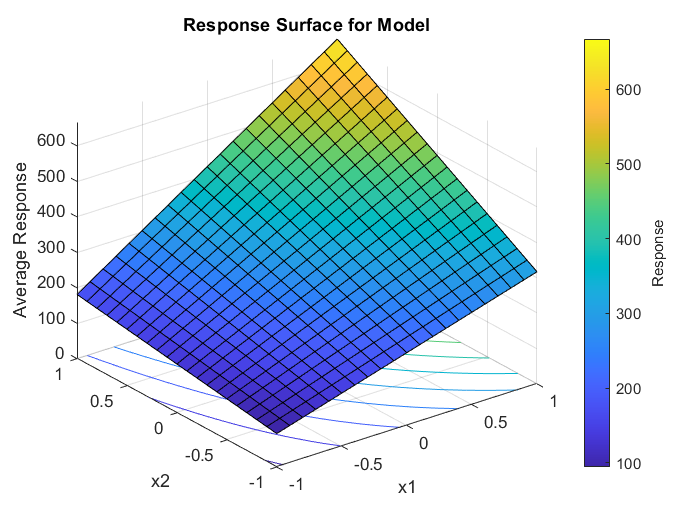

% Create grid
% Nodes
res = 0.1; % Resolution
x1 = [min(fx1):res:max(fx2)]; % Column vector from low level to high level in increments of resolution.
x2 = [min(fx2):res:max(fx2)];
x3 = [min(fx3):res:max(fx3)];

nx1 = length(x1); % Returns the number of elements in the vector - this becomes
% the nodes on our mesh
nx2 = length(x2);
nx3 = length(x3);

[X1,X2] = meshgrid(x1,x2); % meshgrid function returns 2D grid coordinates

% Extract model parameter estimates, known as the regression coefficients
% beta's
betas817 = mdl8173.Coefficients.Estimate;
mu = betas817(1,1); % Mean
beta1 = betas817(2,1); % Regression coefficient for sweetner factor, beta
beta2 = betas817(3,1);
beta3 = betas817(4,1);
beta12 = betas817(5,1);
beta13 = betas817(6,1);
beta23 = betas817(7,1);

% Evaluate the regression equation at every coordinate within the grid.
% Initalize variable to hold the evaluated equation.
% Effects from Factor 1 and 2 only
Z12 = nan; % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx2 % Second loop; j is the index of the grid's column
        Z12(i,j) = mu + beta1*X1(i,j) + beta2*X2(i,j) + beta12*X1(i,j)*X2(i,j);
    end
end

% Surface plot
figure;
surfc(X1,X2,Z12); % surfc creates a surface and contour plot
c1 = colorbar;
c1.Label.String = 'Response';
title('Response Surface for Model');
xlabel('x1');
ylabel('x2');
zlabel('Average Response');

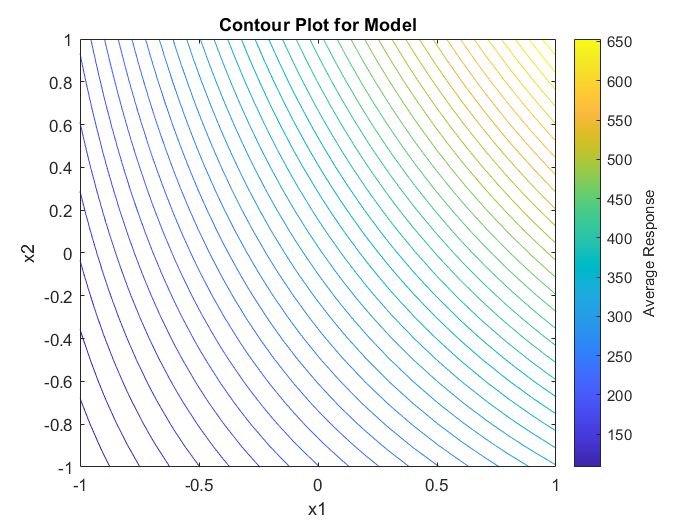


% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X1,X2,Z12,cl) % 2D contour plot
title('Contour Plot for Model');
xlabel('x1');
ylabel('x2');
zlabel('x3');
c2 = colorbar;
c2.Label.String = 'Average Response';

Terms 2 and 3 only.

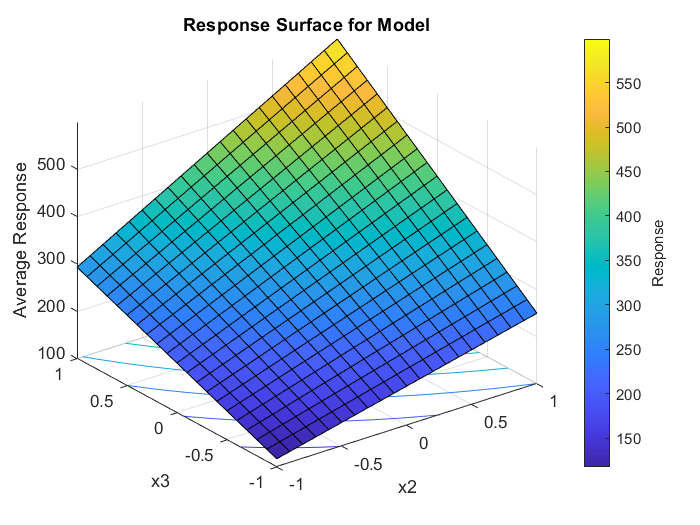

[X2,X3] = meshgrid(x2,x3); % meshgrid function returns 2D grid coordinates
% Effects from Factor 2 and 3 only
Z23 = nan; % This is the variable to hold the value of the response.
for i = 1:nx2 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column
        Z23(i,j) = mu + beta2*X2(i,j) + beta3*X3(i,j) + beta23*X2(i,j)*X3(i,j);
    end
end

% Surface plot
figure;
surfc(X2,X3,Z23); % surfc creates a surface and contour plot
c1 = colorbar;
c1.Label.String = 'Response';
title('Response Surface for Model');
xlabel('x2');
ylabel('x3');
zlabel('Average Response');

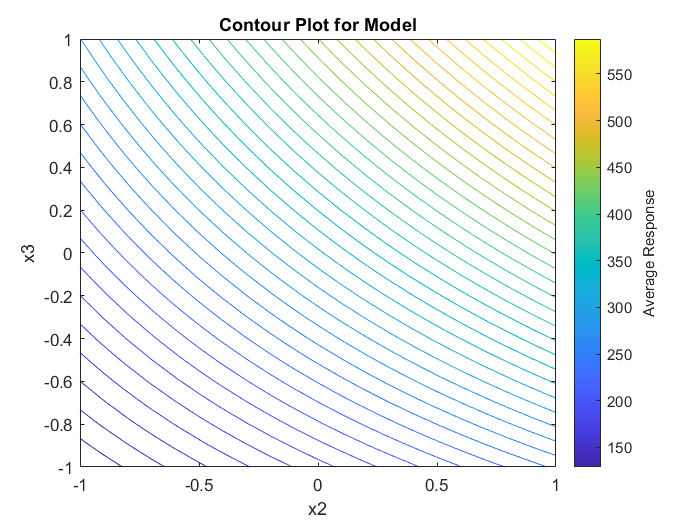


% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X2,X3,Z23,cl) % 2D contour plot
title('Contour Plot for Model');
xlabel('x2');
ylabel('x3');
zlabel('Average Response');
c2 = colorbar;
c2.Label.String = 'Average Response';

Terms 1 and 3 only.

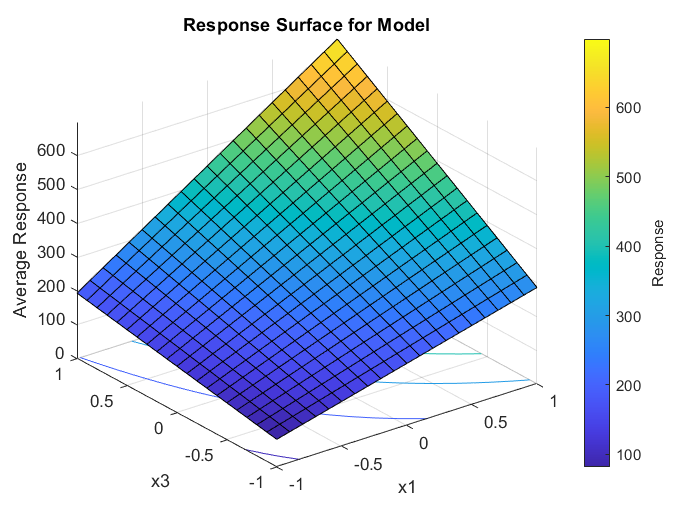

[X1,X3] = meshgrid(x1,x3); % meshgrid function returns 2D grid coordinates
% Effects from Factor 2 and 3 only
Z13 = nan; % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column
        Z13(i,j) = mu + beta1*X1(i,j) + beta3*X3(i,j) + beta13*X1(i,j)*X3(i,j);
    end
end

% Surface plot
figure;
surfc(X1,X3,Z13); % surfc creates a surface and contour plot
c1 = colorbar;
c1.Label.String = 'Response';
title('Response Surface for Model');
xlabel('x1');
ylabel('x3');
zlabel('Average Response');

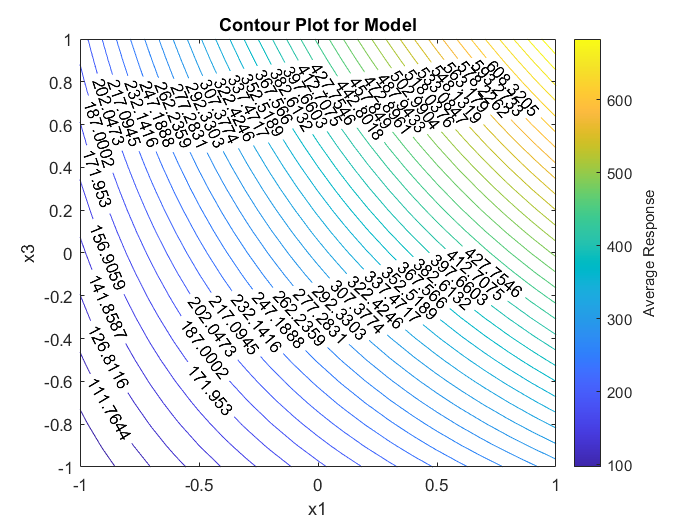


% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X1,X3,Z13,cl,'ShowText','on') % 2D contour plot
title('Contour Plot for Model');
xlabel('x1');
ylabel('x3');
c2 = colorbar;
c2.Label.String = 'Average Response';

Standard Deviation

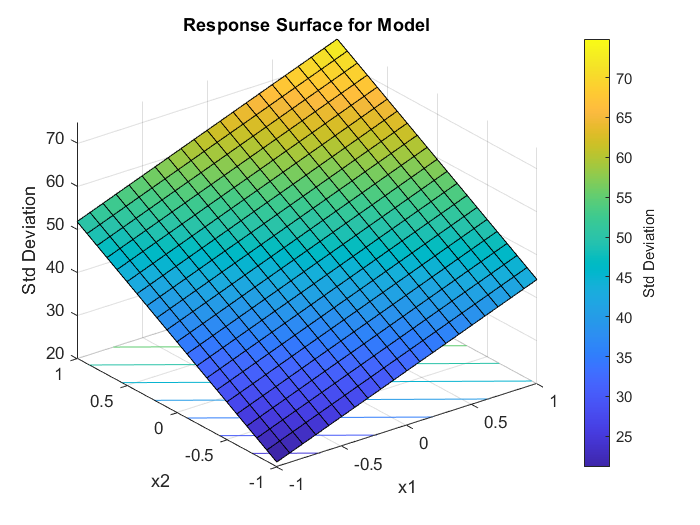

% Create grid
% Nodes
res = 0.1; % Resolution
x1 = [min(fx1):res:max(fx2)]; % Column vector from low level to high level in increments of resolution.
x2 = [min(fx2):res:max(fx2)];
x3 = [min(fx3):res:max(fx3)];

nx1 = length(x1); % Returns the number of elements in the vector - this becomes
% the nodes on our mesh
nx2 = length(x2);
nx3 = length(x3);

[X1,X2] = meshgrid(x1,x2); % meshgrid function returns 2D grid coordinates

% Extract model parameter estimates, known as the regression coefficients
% beta's
betas8172 = mdl8172.Coefficients.Estimate;
mu = betas8172(1,1); % Mean
beta1s = betas8172(2,1); % Regression coefficient for sweetner factor, beta
beta2s = betas8172(3,1);
beta3s = betas8172(4,1);

% Evaluate the regression equation at every coordinate within the grid.
% Initalize variable to hold the evaluated equation.
% Effects from Factor 1 and 2 only
Z12s = nan; % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx2 % Second loop; j is the index of the grid's column
        Z12s(i,j) = mu + beta1s*X1(i,j) + beta2s*X2(i,j);
    end
end

% Effects from Factor 1 and 3 only
Z13s = nan; % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column
        Z13s(i,j) = mu + beta1s*X1(i,j) + beta3s*X3(i,j);
    end
end

% Surface plot
figure;
surfc(X1,X2,Z12s); % surfc creates a surface and contour plot
c1 = colorbar;
c1.Label.String = 'Std Deviation';
title('Response Surface for Model');
xlabel('x1');
ylabel('x2');
zlabel('Std Deviation');

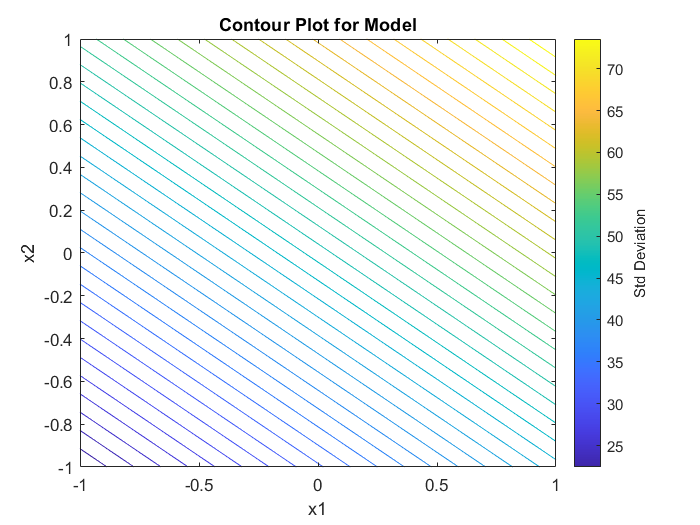


% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X1,X2,Z12s,cl) % 2D contour plot
title('Contour Plot for Model');
xlabel('x1');
ylabel('x2');
zlabel('S');
c2 = colorbar;
c2.Label.String = 'Std Deviation';
hold off;

Contour Plot Overlay

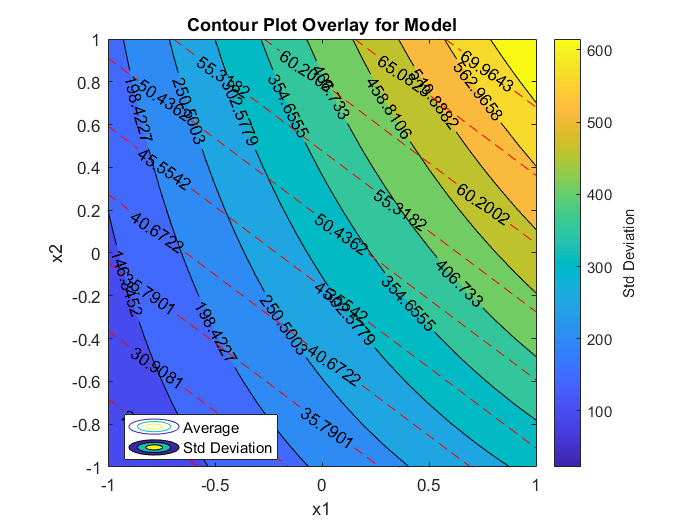

% Factors x1 and x2
hold on;
% Contour plot
cl = 10; % Number of contour levels (for increased resolution)
contourf(X1,X2,Z12,cl,'showtext','on') % 2D contour plot
% Show text display contour labels

% Contour plot
cl = 10; % Number of contour levels (for increased resolution)
contour(X1,X2,Z12s,cl,'--r','showtext','on') % 2D contour plot
title('Contour Plot Overlay for Model');
xlabel('x1');
ylabel('x2');
axis equal; % Use the same length for the data units along each axis.
legend('Average','Std Deviation','location','best');
hold off;

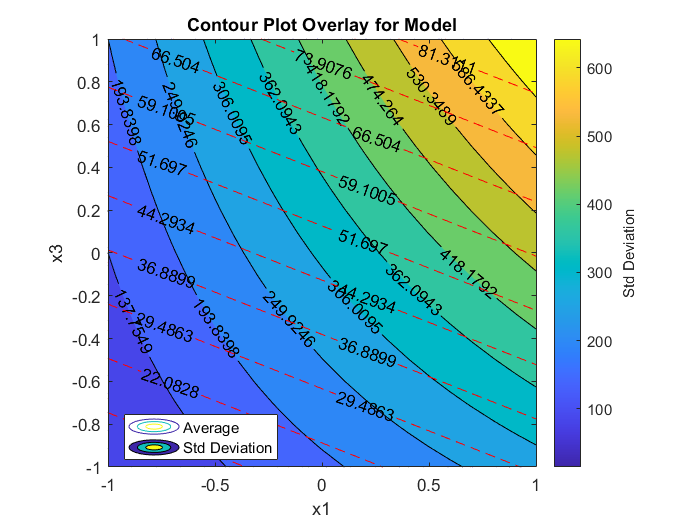

% Factors x1 and x3
hold on;
% Contour plot
cl = 10; % Number of contour levels (for increased resolution)
contourf(X1,X3,Z13,cl,'showtext','on') % 2D contour plot
% Show text display contour labels

% Contour plot
cl = 10; % Number of contour levels (for increased resolution)
contour(X1,X3,Z13s,cl,'--r','showtext','on') % 2D contour plot
title('Contour Plot Overlay for Model');
xlabel('x1');
ylabel('x3');
axis equal; % Use the same length for the data units along each axis.
legend('Average','Std Deviation','location','best');
hold off;

Problem 8.17 - 3^3 Full-factorial design, cont.

In conclusion, to hit an Average target of 500 while maintaining std deviation low, the factor-level settings should be set to:

x1 = ~ 1.0

x2 = ~ 0.3

x3 = ~ 0.2

Problem 8.17. To hit an Average target of 500 while maintaining std deviation low, the factor-level settings should be set to:

x1 = ~ 1.0

x2 = ~ 0.3

x3 = ~ 0.2

-2.